# Cinematica Directa

En este archivo se encuentra los calculos de la cinematica directa para un **Scara de 3DoF** y un **Antropomórfico R3 sin codo**

## Antropomorfico (3R)

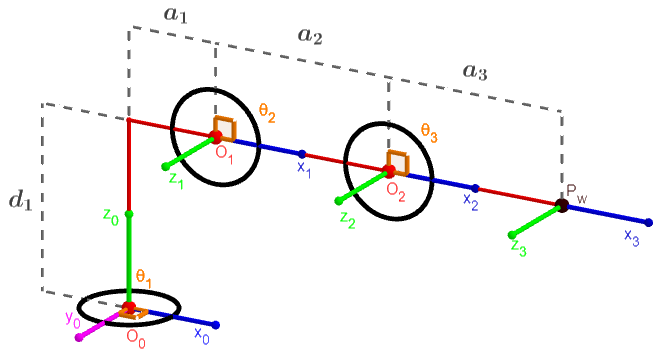

d_1=95.91;
a_2=66.76;
a_3=130.45;
eslavones=3;
%Indica "1" Para Las Variables De Juntura%
matriz=[1, d_1, 90, 0;
        1, 0,   0, a_2;
        1, 0,   0, a_3];
Tabla=T_DH(eslavones,matriz)  %Crea la Tabla D-H

$$Tabla = \left(\begin{array}{cccc} \theta_{n} & d_{n} & \alpha_{n} & a_{n}\\ \theta_{1} & \frac{6287}{100} & 90 & \frac{29}{2}\\ \theta_{2} & 0 & 0 & \frac{135}{2}\\ \theta_{3} & 0 & 0 & \frac{2207}{25} \end{array}\right)$$

#### Variables de Juntura

t1=51.5;
t2=97;
t3=51;
A_T=DH(eslavones,matriz,[t1,t2,t3])

A_T =    -0.5279   -0.3299    0.7826  -42.6994
   -0.6637   -0.4147   -0.6225  -53.6806
    0.5299   -0.8480         0  176.6481
         0         0         0    1.0000


#### Para matrices por eslabon "An"

%An=parametros(0,1,t1,d_1,90,a_1) %Rellenarla: (0,x,matriz(:,1),matriz(:,2),matriz(:,3),matriz(:,4)

## Scara (P2R)

#### 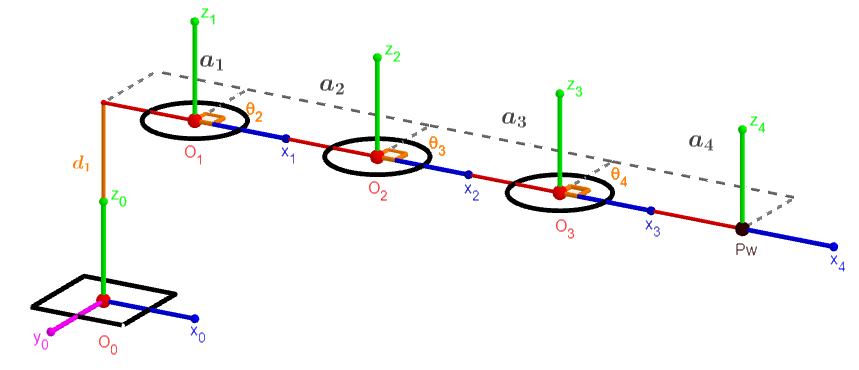

a_s1=47.3;
a_s2=149.1;
a_s3=148.8;
eslavones_s=3;
%Indica "1" Para Las Variables De Juntura%
matriz_s=[0, 1, 0, a_s1;
          1, 0, 0, a_s2;
          1, 0, 0, a_s3;       
];
Tabla_s=T_DH(eslavones_s,matriz_s) %Crea la Tabla D-H

$$Tabla\_s = \left(\begin{array}{cccc} \theta_{n} & d_{n} & \alpha_{n} & a_{n}\\ 0 & d_{1} & 0 & \frac{473}{10}\\ \theta_{2} & 0 & 0 & \frac{1491}{10}\\ \theta_{3} & 0 & 0 & \frac{744}{5} \end{array}\right)$$

#### Variables de Juntura

ds1=221;
ts2=2.5;
ts3=4;
A_Ts=DH(eslavones_s,matriz_s,[ds1,ts2,ts3])

A_Ts =     0.9936   -0.1132         0  344.1016
    0.1132    0.9936         0   23.3483
         0         0    1.0000  221.0000
         0         0         0    1.0000


#### Para matrices por eslabon "An"

%Ans=parametros(0,1,0,ds1,0,a_s1) %Rellenarla: (0,x,matriz_s(:,1),matriz_s(:,2),matriz_s(:,3),matriz_s(:,4)

## Antropomorfico (R6)

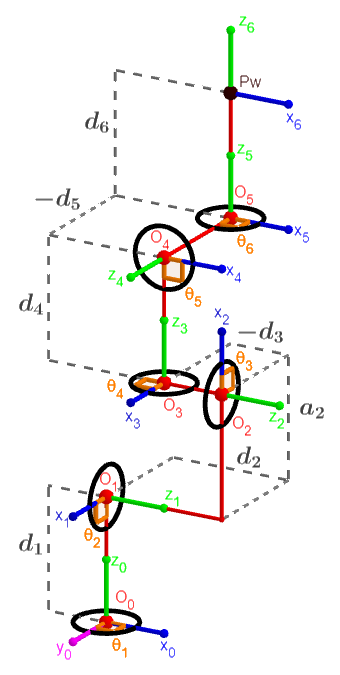

d_r1=115;
d_r2=30;
a_r2=280;
d_r3=20;
d_r4=140+105;
d_r5=28.5+28.5;
d_r6=105+130;
eslavones_r=6;
%Indica "1" Para Las Variables De Juntura%
matriz_r=[1,  d_r1, -90,    0;
          1,  d_r2,   0, a_r2;
          1, -d_r3,  90,    0;
          1,  d_r4,  90,    0;
          1, -d_r5, -90,    0;
          1,  d_r6,   0,    0];
Tabla_r=T_DH(eslavones_r,matriz_r) %Crea la Tabla D-H

$$Tabla\_r = \left(\begin{array}{cccc} \theta_{n} & d_{n} & \alpha_{n} & a_{n}\\ \theta_{1} & 115 & -90 & 0\\ \theta_{2} & 30 & 0 & 280\\ \theta_{3} & -20 & 90 & 0\\ \theta_{4} & 245 & 90 & 0\\ \theta_{5} & -57 & -90 & 0\\ \theta_{6} & 235 & 0 & 0 \end{array}\right)$$

#### Variables de Juntura

tr1=92.5;
tr2=132.5;
tr3=143;
tr4=167.5;
tr5=129;
tr6=180;
A_Tr=DH(eslavones_r,matriz_r,[tr1,tr2,tr3,tr4,tr5,tr6])

A_Tr =    -0.1673   -0.9763    0.1375   96.8698
    0.7081   -0.0219    0.7058 -265.9487
   -0.6861    0.2154    0.6949   83.0690
         0         0         0    1.0000


#### Para matrices por eslabon "An" (remplazar los "1" de las matrices por las variables de juntura)

%Anr=parametros(0,1,tr1,d_r1,-90,0) %Rellenarla: (0,x,matriz_r(:,1),matriz_r(:,2),matriz_r(:,3),matriz_r(:,4)

function Matriz_DH=DH(n,matriz,junturas)%Funcion Para Matriz DH (Final)
    Matriz_T=eye(4);
    for i=1:n
        angz=matriz(i,1);
        d=matriz(i,2);
        angx=matriz(i,3);
        a=matriz(i,4);
        for j=1:2
            if matriz(i,1)==1
               angz=junturas(i); 
            else
                d=junturas(i); 
            end
        end                
        Ma_S=parametros(0,1,angz,d,angx,a);
        Matriz_T=Matriz_T*Ma_S; %Matrices DH PostMultiplicacion (A01*A12,A01*A12*A23...)
    end
    Matriz_DH=Matriz_T;  %Matriz DH (A01*....A(n-1,n))
end
function Homogenea=parametros(tipo,cual,angz,d,angx,a)%Calculo de la Matriz homogenea de DH (por eslabon)
%Para Matriz Completamente simbolica enviar (1,n,1,1,1,1)
%Para Matriz con Variables de Juntura Rotacionales Simbolicas enviar (2,n,1,d,angx,a)
%Para Matriz Evaluada o con Variables de Juntura Prismaticas Simbolicas enviar (0,n,angz,(1/d),angx,a)
    Tabla_D=SB(cual);
    vec=[angz,d,angx,a];   
    if tipo==0      
        if (vec(2)==1)
            fila=Tabla_D(cual,2);
        else
            fila=vec(2);    
        end        
        Homogenea=[cosd(angz), -sind(angz)*cosd(angx),  sind(angz)*sind(angx), a*cosd(angz);
                   sind(angz),  cosd(angz)*cosd(angx), -cosd(angz)*sind(angx), a*sind(angz);
                            0,             sind(angx),             cosd(angx),         fila;
                            0,                      0,                      0,            1];
    elseif tipo==1  
        for j=1:cual
            for k=1:4
                if (vec(k)==1)
                   fila(k)=Tabla_D(j,k);
                else
                    fila(k)=vec(k);
                end
            end
        end     
        
        %Calculo de la Matriz Simbolica homogenea de DH (por eslabon)
        Homogenea=[cos(fila(1)), -sin(fila(1))*cos(fila(3)),  sin(fila(1))*sin(fila(3)), fila(4)*cos(fila(1));
                   sin(fila(1)),  cos(fila(1))*cos(fila(3)), -cos(fila(1))*sin(fila(3)), fila(4)*sin(fila(1));
                    0,                  sin(fila(3)),            cos(fila(3)),           fila(2);
                    0,                          0,                    0,           1];
    else
        if (vec(1)==1)
            fila=Tabla_D(cual,1);
        else
            fila=vec(1);    
        end 
        %Calculo de la Matriz Simbolica Con Theta homogenea de DH (por eslabon)
        Homogenea=[cos(fila(1)), -sin(fila(1))*cosd(angx),  sin(fila)*sind(angx), a*cos(fila);
                   sin(fila(1)),  cos(fila(1))*cosd(angx), -cos(fila)*sind(angx), a*sin(fila);
                           0,                  sind(angx),               cosd(angx),              d;
                           0,                     0,                     0,           1];
    end
end
function simbolos=SB(n)
    T=[sym('theta_%d',[1 n+1])];
    d=[sym('d_%d',    [1 n+1])];
    A=[sym('alpha_%d',[1 n+1])];
    a=[sym('a_%d',    [1 n+1])];
    simbolos=[transpose(T) transpose(d) transpose(A) transpose(a)];
end
function Tabla_DH=T_DH(i,matrix) %Funcion para Tabla de Parametros DH
    syms theta_n d_n alpha_n a_n
    Tabla_D=SB(i-1);
    for j=1:i
        for k=1:4
            if (matrix(j,k)~=1 && matrix(j,k)~=0)
                Tabla_D(j,k)=1;
            end
        end        
        Tabla_T(j,:)=Tabla_D(j,:).*matrix(j,:);
    end
    Tabla_DH=[theta_n d_n alpha_n a_n;Tabla_T];
end